classpath = 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@LightSim\'

classpath = 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@LightSim\'

userpath = 'C:\Users\wayne\Documents\GitHub\'

userpath = 'C:\Users\wayne\Documents\GitHub\'


% NEC
fn_cs2000 = [classpath '0605\colorchecker_test_result_nec.mat'];
fn_cl500a = [classpath 'cl500a_0608\CL500a_nec.xlsx'];
fn_i1 = [classpath 'nec_i1_0608\i1data_nec.mat'];
fn_spyder = [classpath 'nec_0607\spyder_nec.mat'];

% HP
% fn_cs2000 = [classpath '0605\colorchecker_test_result_hp.mat'];
% fn_cl500a = [classpath 'cl500a_0608\CL500a_hp.xlsx'];
% fn_i1 = [classpath 'hp_i1_0608\i1data_hp.mat'];
% fn_spyder = [classpath 'hp_0606\spyder0606.mat'];

% Rift
% fn_cs2000 = [classpath '0605\colorchecker_test_result_rift.mat'];
% fn_cl500a = [classpath 'cl500a_0608\CL500a_rift.xlsx'];
% fn_i1 = [classpath 'rift_i1_0608\i1data_rift.mat'];
% fn_spyder = [classpath 'rift0607\spyder_rift.mat'];

addpath([userpath 'color_performance_review'])
addpath([userpath 'color_conversion'])

data_cs2000 = DeviceData;
data_cl500a = DeviceData;
data_i1 = DeviceData;
data_lightsim = DeviceData;
data_spyder = DeviceData;

data_cs2000.construct_by_cs2000(fn_cs2000)
data_lightsim.construct_by_target(fn_cs2000)
data_cl500a.construct_by_CL500a(fn_cl500a)

data_i1.construct_by_i1(fn_i1)
data_spyder.construct_by_spyder(fn_spyder,3)

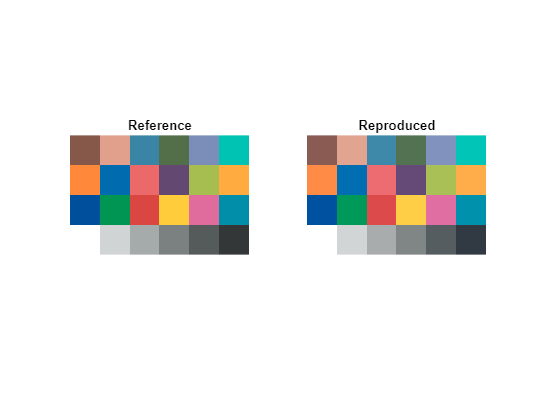

a=data_cs2000;
b=data_spyder;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

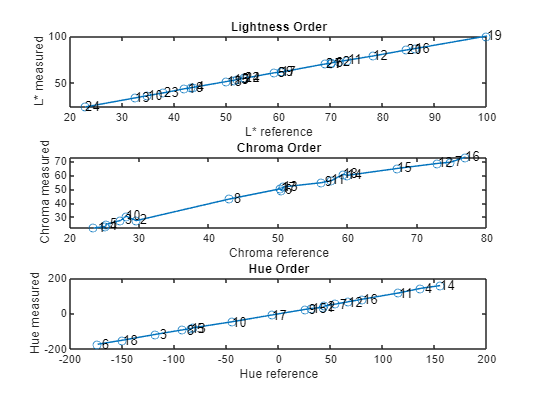

clf; cpr.evaluate_order(a,b);

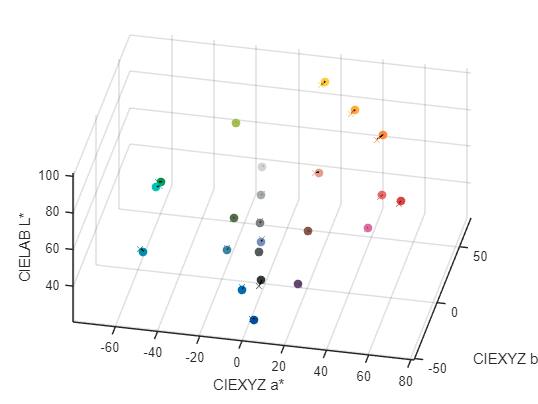

clf; cpr.show3dquiver(a,b); view([12 32])

dEmean = 1.6099

dEstd = 0.9533

dEmax = 5.1798

dEmin = 0.4309

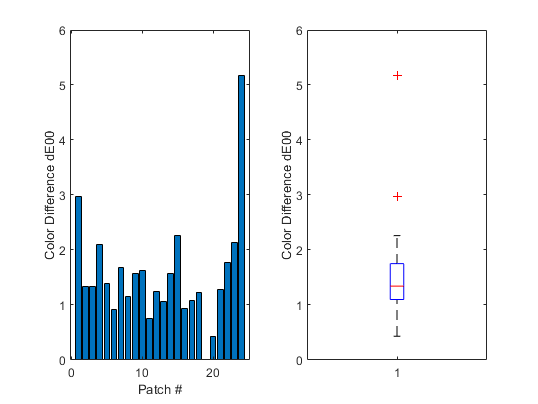

clf; cpr.evaluate_dE(a,b);

cce_measured = 0.9898

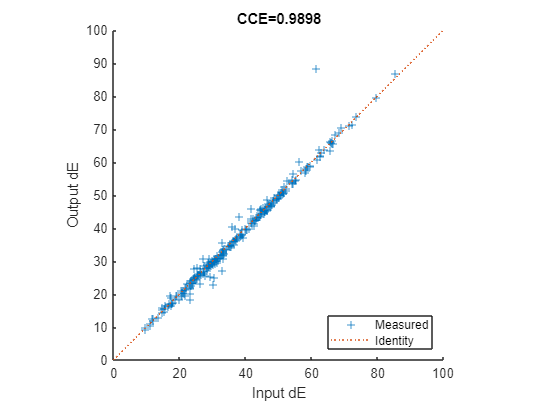

clf; cpr.evaluate_CCE(a,b);

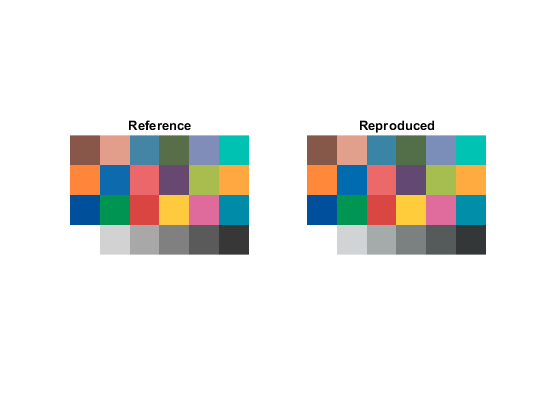

a=data_lightsim;
b=data_cs2000;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

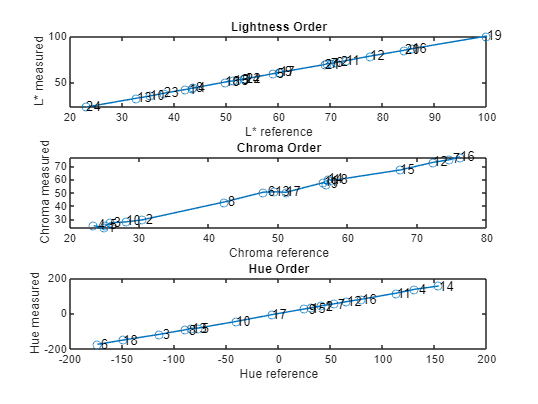

clf; cpr.evaluate_order(a,b);

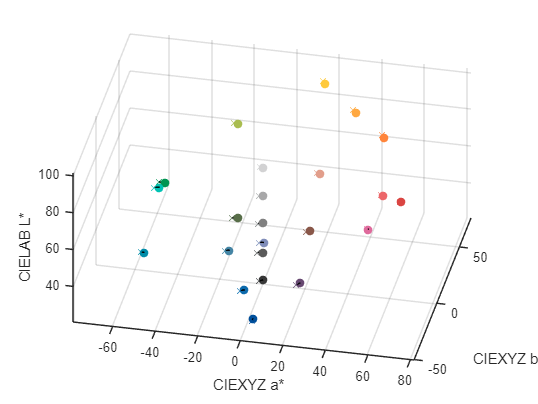

clf; cpr.show3dquiver(a,b); view([12 32])

ans = 'Adjusting reference by 1.000000X'

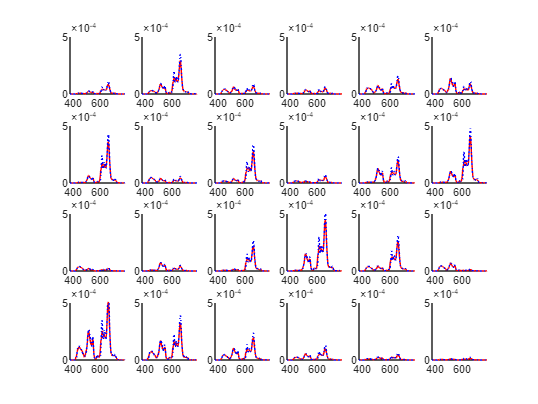

clf; b.compare_with_ref(a)

dEmean = 1.3799

dEstd = 0.8271

dEmax = 3.2965

dEmin = 0.3494

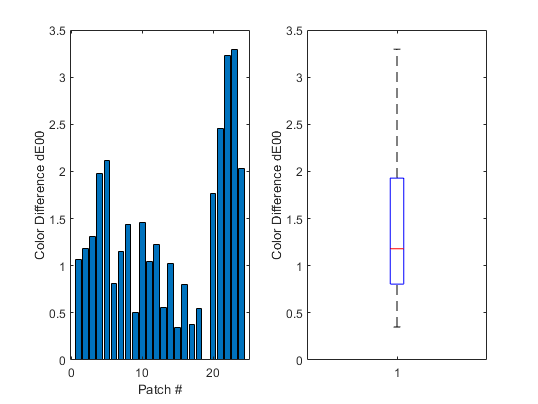

clf; cpr.evaluate_dE(a,b);

cce_measured = 1.0064

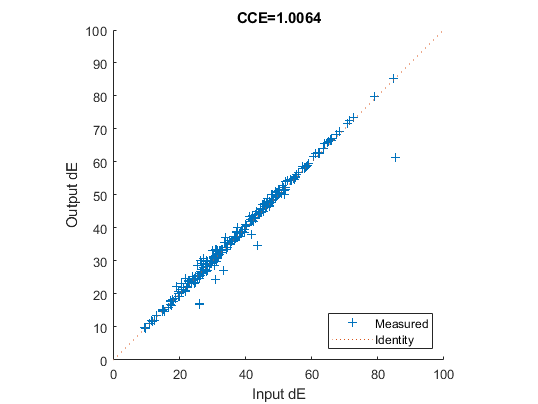

clf; cpr.evaluate_CCE(a,b);

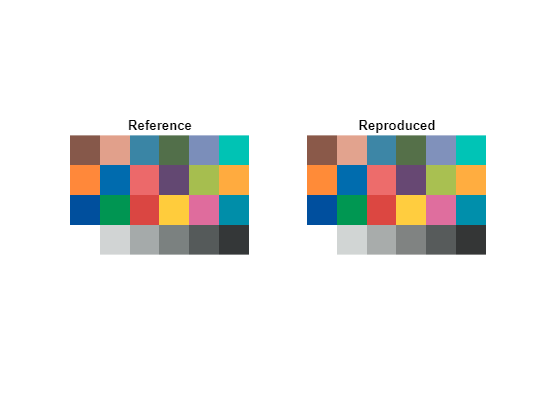

a=data_cs2000;
b=data_cl500a;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

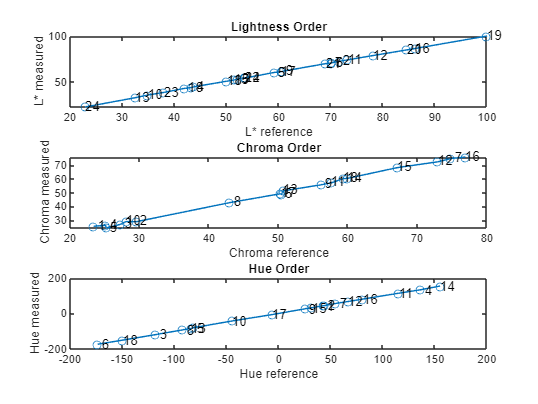

clf; cpr.evaluate_order(a,b);

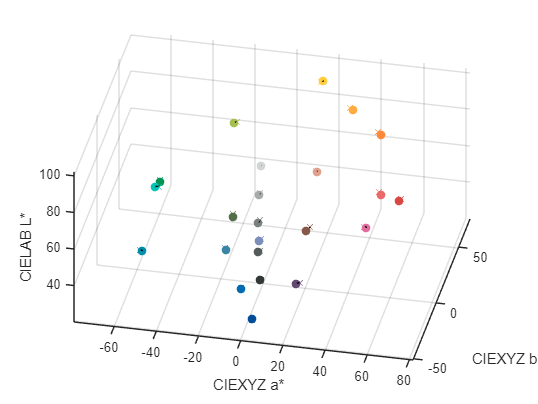

clf; cpr.show3dquiver(a,b); view([12 32])

ans = 'Adjusting reference by 1.000000X'

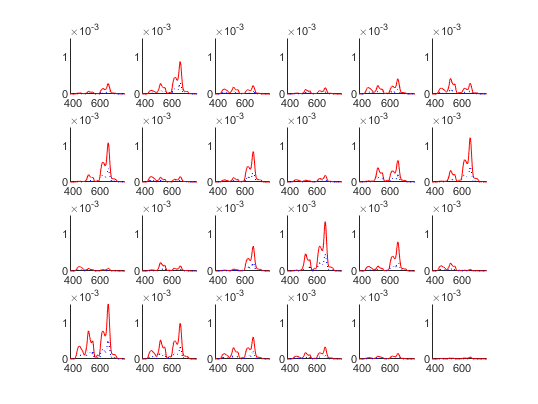

clf; b.compare_with_ref(a)

dEmean = 0.8315

dEstd = 0.3732

dEmax = 1.6812

dEmin = 0.1918

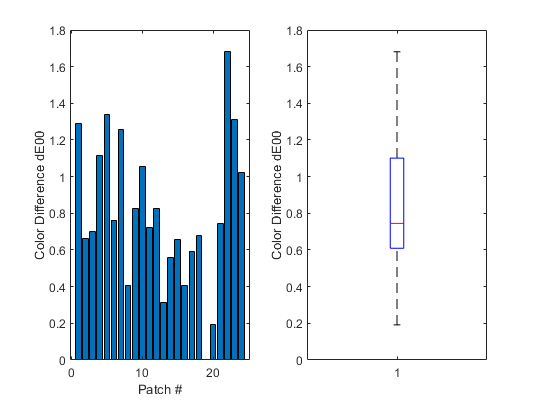

clf; cpr.evaluate_dE(a,b);

cce_measured = 1.0041

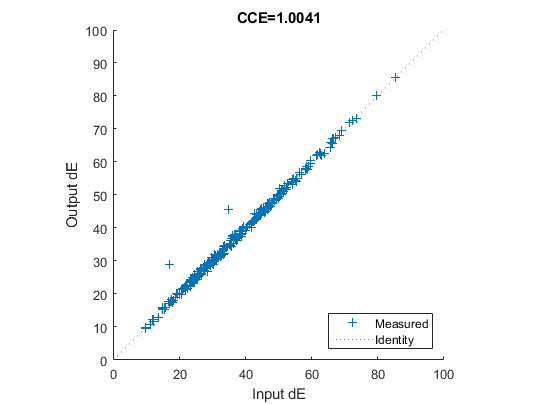

clf; cpr.evaluate_CCE(a,b);

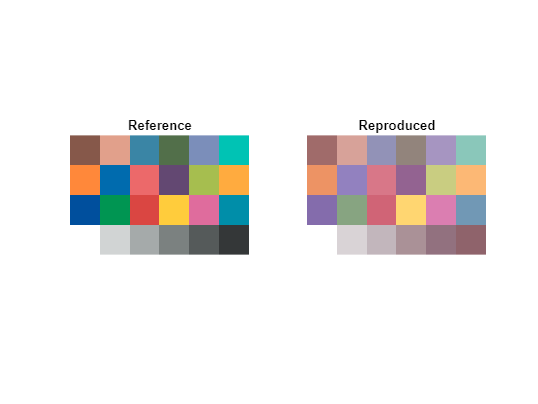

a=data_cs2000;
b=data_i1;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

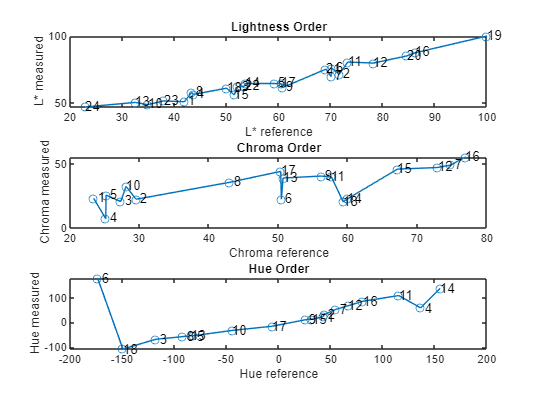

clf; cpr.evaluate_order(a,b);

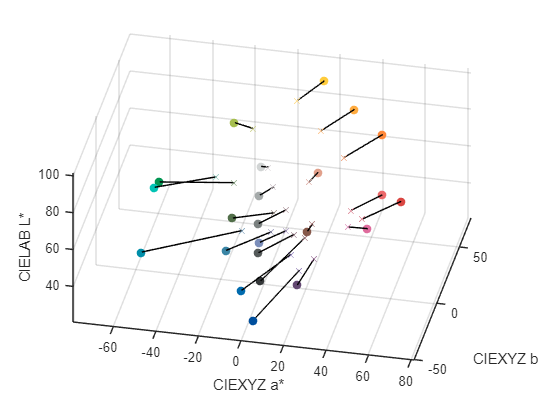

clf; cpr.show3dquiver(a,b); view([12 32])

ans = 'Adjusting reference by 1.000000X'

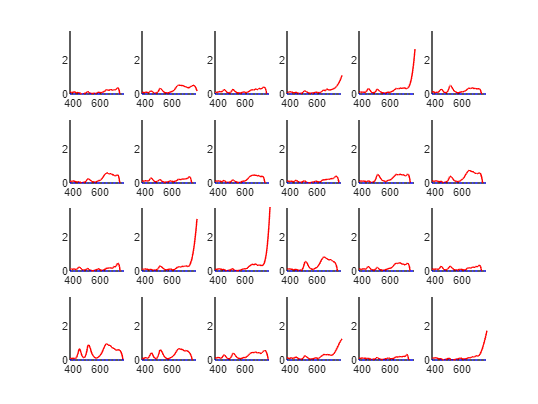

clf; b.compare_with_ref(a)

dEmean = 14.4612

dEstd = 7.7764

dEmax = 27.6262

dEmin = 5.1238

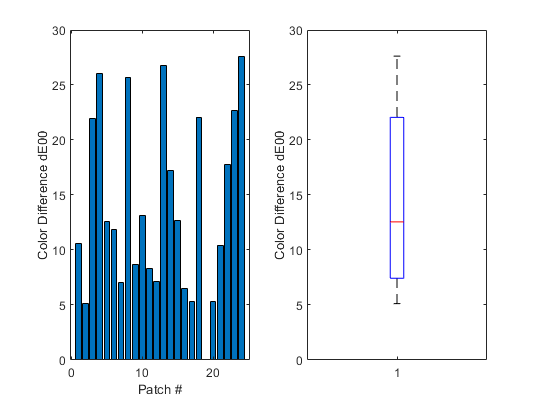

clf; cpr.evaluate_dE(a,b);

cce_measured = 0.7488

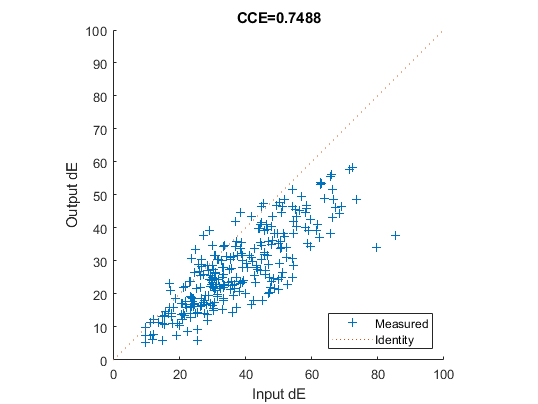

clf; cpr.evaluate_CCE(a,b);

function compare_dataspec (a,b)
cpr = ColorPerformanceReview;
figure; cpr.evaluate_visual(a,b);
cpr.evaluate_order(a,b);
cpr.show3dquiver(a,b); view([12 32])
b.compare_with_ref(a)
end